# Getting Started with 4DNvestigator

## 4DNvestigator Overview

### What is the 4DNvestigator

    The 4DNvestigator is a toolbox for analyzing time-series genome-wide chromosome conformation capture (Hi-C) and gene expression (RNA-seq) data.  

### Initial setup of 4DNvestigator Environment

close all, clear all
restoredefaultpath
addpath(genpath(pwd))

### Loading Processed Hi-C and RNA-seq Data

Index_Loc = '\\172.17.109.24\internal_4dn\projects\4DNvestigator_data\myodData\sampleMyodDataIndexTp-48_8_80.xlsx';
Data_Loc = '\\172.17.109.24\internal_4dn\projects\4DNvestigator_data\myodData\';


if exist('sampleMyodDataIndexTp-48_8_80.xlsx','file')==2
    [dataInfo] = fdnLoadUserInput(Index_Loc);
    [H] = fdnLoadHic(Data_Loc,dataInfo,'single');
    [R] = fdnLoadRnaseq(Data_Loc,dataInfo,H);
end

## Example Usage of the 4DNvestigator Tools

### Feature Analyzer

The Feature Analyzer takes in Hi-C and RNA-seq data (formatted as shown above) and computes the changes in structure and function between samples. For ease of use, a pre-formatted dataset from a cellular reprogramming experiment is used as an example.

The function **featureAnalyzerExample** requires the parameters **Data_Loc** and **Folder_Result** which denote the locations where the data can be accessed and the output figure is stored, respectively. The remaining parameters, **chrSelect**, **dimReduc**, and **binSize**, correspond to the chromosome used for analysis, the method of dimension reduction used for visulization, and the desired resolution of the data. The values assigned to these parameters shown below are the default if none are specified.

Data_Loc = '\\172.17.109.24\internal_4dn\projects\4DNvestigator_data\myodData\myodData.mat';
Folder_Result = 'results\featureAnalyzerResults';
chrSelect = 11;
dimReduc = 'pca';
binSize = 1E5;
featureAnalyzerExample(Data_Loc, Folder_Result, chrSelect, dimReduc, binSize)

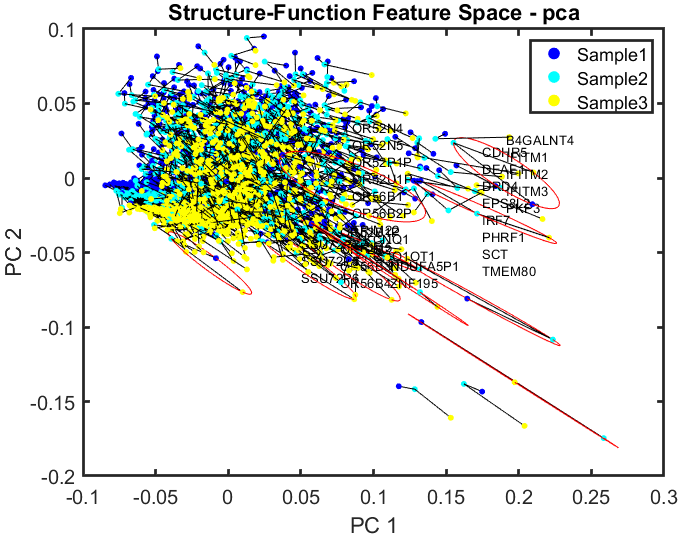

### Von Neumann Entropy

#### Simple Von Neumann Entropy - Two Cell Types

Von Neumann Entropy is calculated for Hi-C data (formatted as shown above) and can be used to compare the entropy of multiple cell types. In this example, we show two cell types, fibroblast and stem cell, to highlight the differences in chromatin organization.

The function **vneExample** requires the parameters **Data_Loc** and **Folder_Result** which denote the locations where the data can be accessed and the output figure is stored, respectively. The remaining parameters, **chrSelect**, **bpFrag**, and **binSize**, correspond to the chromosome used for analysis, the choice of coordinates (base pair = BP or fragment = FRAG), and the desired resolution of the data. The values assigned to these parameters shown below are the default if none are specified.

Data_Loc = {'\\172.17.109.24\internal_4dn\projects\4DNvestigator_data\4DNFIFLJLIS5.hic',...
            '\\172.17.109.24\internal_4dn\projects\4DNvestigator_data\4DNFIOX3BGNE.hic'};
Folder_Result = 'results\vneExampleResults';
chrSelect = 14;
bpFrag = 'BP';
binSize = 1E5;

vneExample(Data_Loc, Folder_Result, chrSelect, bpFrag, binSize)

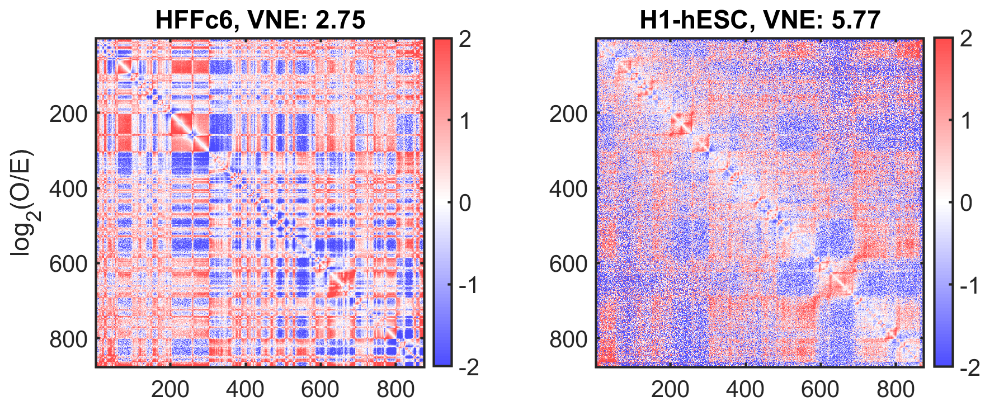

#### Expanded Von Neumann Entropy - Many Cell Types

The function **vneExampleExpanded **is similar to the simple VNE function above but highlights that more than two cell types can be calculated at once.

Data_Loc = {'\\172.17.109.24\internal_4dn\projects\4DNvestigator_data\4DNFIFLJLIS5.hic';...
            '\\172.17.109.24\internal_4dn\projects\4DNvestigator_data\4DNFIOX3BGNE.hic';...
            'https://hicfiles.s3.amazonaws.com/hiseq/imr90/in-situ/combined.hic';...
            'https://hicfiles.s3.amazonaws.com/hiseq/huvec/in-situ/combined.hic';...
            'https://hicfiles.s3.amazonaws.com/hiseq/gm12878/in-situ/combined.hic';...
            'http://hicfiles.s3.amazonaws.com/hiseq/rpe1/DarrowHuntley-2015/WT-combined.hic'};
Folder_Result = 'results\vneExampleExpandedResults';
chrSelect = 14;
bpFrag = 'BP';
binSize = 1E5;

vneExampleExpanded(Data_Loc, Folder_Result, chrSelect, bpFrag, binSize) 

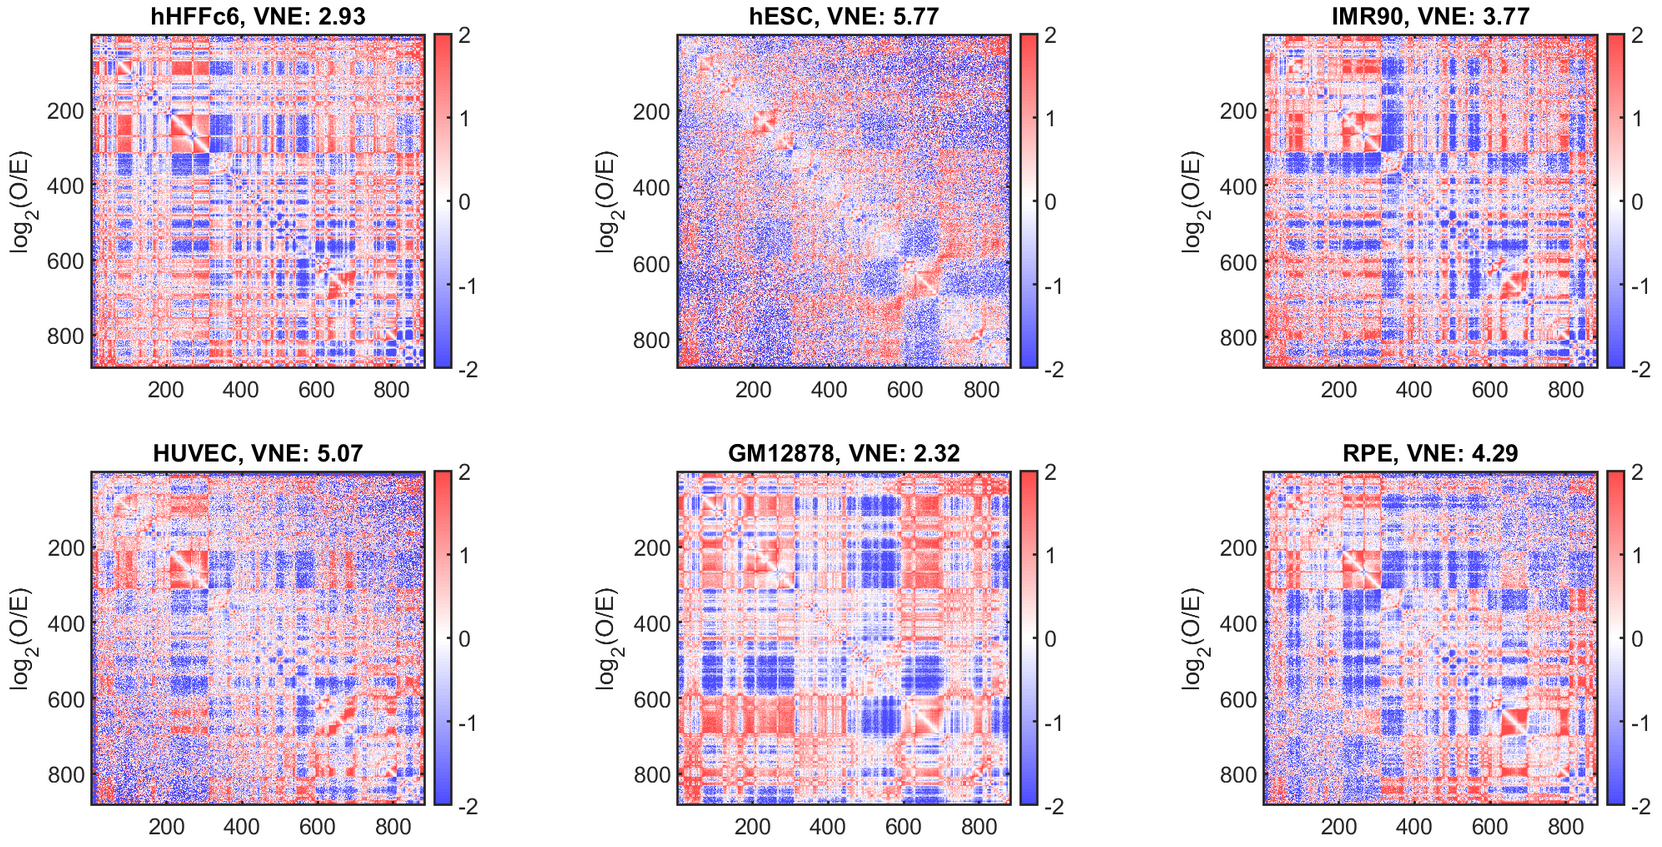

### Larntz-Perlman

close all
Data_Loc = '\\172.17.109.24\internal_4dn\projects\4DNvestigator_data\myodData\myodData.mat';
Folder_Result = 'results\lpExampleResults';

lpExample(Data_Loc, Folder_Result);

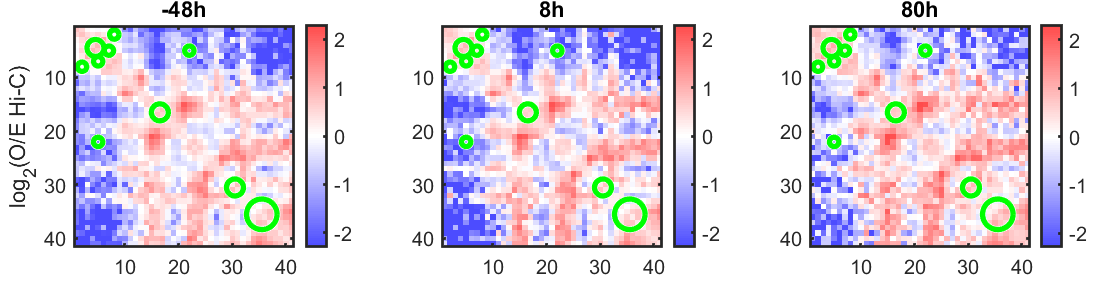

### Network Analysis

Data_Loc = '\\172.17.109.24\internal_4dn\projects\4DNvestigator_data\networkData\'; %%% data input folder
Folder_Result = 'results\networkExamplesResults'; %%% output result file name

networkExamples(Data_Loc, Folder_Result);